# *ROV 6-DOF Modelling and Control* 

clearvars
close('all')
Simulink.sdi.clear
 


% load bus data
load("data\busdef.mat");


# *INPUTS*

## Physical constants

phy.g = 9.81;    % Acc. due to gravity (m/s^2)
phy.rho = 1000;  % Density of water (kg/m^3)

## Rigid-Body (ROV)

    ***Rigid body mass ***$\left(\textrm{kg}\right)$

rb.m = 13.5;       % Mass of ROV (kg)  +  2kg of addedd mass/ ballast

    ***Location of centre of gravity ***$\left(m\right)$

rb.xg = 0;      rb.yg = 0;      rb.zg = 0;      % Location of CG 


    ***Moment of Inertia ***$\left(\textrm{kg}\ldotp m^2 \right)$

rb.Ix = 0.26;      rb.Iy = 0.23;      rb.Iz = 0.37;   

rb.Ixy = 0;    rb.Iyz = 0;     rb.Ixz = 0;     

    ***Dimensions of ROV  ***$\left(m\right)$

rb.L = 0.46;        rb.W = 0.58;       rb.H = 0.38;       


   *** Location of Centre of Buoyancy ***$\left(m\right)$

% Location of centre of Buoyancy
hyd.statics.xb = 0;         hyd.statics.yb = 0;         hyd.statics.zb = -0.01;         

    ***Volume Displaced by Vehicle ***$\left.{\left(m\right.}^3 \right)$

% Nominal Volume displaced by vehicle
hyd.statics.delV = 0.0135;       % Volume displaced by vehicle (m^3)     

## Hydrodynamics Coefficients

 ***   Added Mass Coefficients***

% Added mass coefficients
hyd.dynamics.der.Xud = -6.36;       hyd.dynamics.der.Kpd = -0.189;  
hyd.dynamics.der.Yvd = -7.12;       hyd.dynamics.der.Mqd = -0.135;   
hyd.dynamics.der.Zwd = -18.68;       hyd.dynamics.der.Nrd = -0.222;   


   *** Linear Damping Coefficients***

% Potential Damping and skin friction coefficients
hyd.dynamics.damping.Xu = -13.7;      hyd.dynamics.damping.Kp = 0;     
hyd.dynamics.damping.Yv = 0;      hyd.dynamics.damping.Mq = -0.8;  
hyd.dynamics.damping.Zw = -33;      hyd.dynamics.damping.Nr = 0; 
  

    ***Quadratic Damping Coefficients***

% Quadratic damping coefficients
hyd.dynamics.damping.Xuu = -141;      hyd.dynamics.damping.Kpp = -1.19;   
hyd.dynamics.damping.Yvv = -217;      hyd.dynamics.damping.Mqq = -0.47;    
hyd.dynamics.damping.Zww = -190;      hyd.dynamics.damping.Nrr = -1.5;      
    

## Ocean currents

% Ocean currents ON or OFF
VC = false;  VC_MODE = "constant";
if VC == true
    VC = 1;
else
    VC = 0;
end
        
if VC_MODE == "constant"
    VC_MODE = 2;
elseif VC_MODE == "random"
    VC_MODE = 1;
end


   *** Input for Constant currents***

    % Irrotational constant ocean currents
    hyd.ocean.flow.constant = 0.25;     % m/s


    ***Input for Random currents***

    % Irrotational Varying ocean currents
    hyd.ocean.flow.varying.Vmax = 0.4;        % Max velocity of varying ocean currents (m/s)
    hyd.ocean.flow.varying.Vmin = 0.05;        % Min velocity of varying ocean currents (m/s)
    % Irrotational Varying Ocean currents sampling (white noise)
    hyd.ocean.flow.noise.ts = 0.9;     % Sampling time (s)
    hyd.ocean.flow.noise.power = 0.3;  % Noise power
    hyd.ocean.flow.varying.mu = 1;



   *** Ocean currents direction***

% Principal Flow axes rotation angles 
hyd.ocean.flow.alpha = 0;        %  Angel of attack (deg)
hyd.ocean.flow.beta = 10;         % Sideslip angle (deg)



## External forces (Tether)

% Activation of tether forces (Enable or Disable)
% Type enable inside parenthesis if tether forces on or disable if off.

TETHER = true;            % Input in small case letter only 
if TETHER == true
    TETHER = 1;
else 
    TETHER = 2;
end


   *** Tether parameters***

ext.tether.N = 11;              % No of nodes
ext.tether.m = 0.043;              % Mass of tether (Kg/m)
ext.tether.d = 0.0075;              % Diameter of tether (m)
ext.tether.Cn = 1.2;             % Normal drag coefficient
ext.tether.Ct = 0.01;             % Tangential drag coefficient
ext.tether.Cint = 0;           % Internal damping constant (Ns/m)
ext.tether.E = 6.437e+10;              % Youngs modulus of tether (N/m^2)
ext.tether.lc = 35;             % tether overall length (m)       

## Thruster Allocation

% Thrust application (Open loop input)
thrust.motion = "surge";      % direction of motion (surge,sway,heave,roll,pitch,yaw)  (note: input must be in small case)
thrust.amount = 50;      % percentage of thrust
thrust.start = 4;       % start time of thrusters (seconds)
thrust.duration = 10;    % seconds


   ***  Horizontal thrusters location ***$\left(\textrm{mm}\right)$

thrust.arm.H.lxi = 156;  thrust.arm.H.lyi = 111;   thrust.arm.H.lzi = 85;   


    *** Moment arms for vertical thrusters ***$\left(\textrm{mm}\right)$

thrust.arm.V.lxi = 120;  thrust.arm.V.lyi = 218;   thrust.arm.V.lzi = 0;   % mm


  ***  Orientation of Horizontal thrusters***

thrust.ang.T1 = pi/4;      thrust.ang.T2 = -pi/4;      
thrust.ang.T3 = 3*pi/4;      thrust.ang.T4 = -3*pi/4;     

## Sensor measurement noise 

sensor.noise.mean = 0;
sensor.noise.sigma = 0.001;
sensor.noise.seed = 0;
sensor.noise.t_sample = 0.001;

## Initial Conditions

  ***  Initial conditions for position and orientation in NED frame***

ics.ita.N = 0;         ics.ita.phi = 0;
ics.ita.E = 0;         ics.ita.theta = 0;    
ics.ita.D = 25;         ics.ita.psi = 0; 
  


    ***Initial conditions for velocities in BODY frame***

ics.vb.u = 0;         ics.vb.p = 0;         
ics.vb.v = 0;         ics.vb.q = 0;        
ics.vb.w = 0;         ics.vb.r = 0;         


    ***Initial conditions for Ocean currents ***$\left(ms^{-1} \right)$

ics.Vc = 0;        % m/s


## Simulation Parameters

% Solver selection
Sim.model = "ROV_Simulation_openloop_ver3";     % Model to be simulated
Sim.solver.type = 'ode45';                  % Solver type (euler,ode2, range-kutta 4,etc)
Sim.solver.stpsz = '0.01';                % step size or timestep

% Simulation time
Sim.ts = 100;  % seconds


%% DERIVED PARAMETERS

% Rigid-body paramaters
rb.rg = [rb.xg,rb.yg,rb.zg];  % CG location (m)
rb.Iyx = -rb.Ixy;
rb.Izy = -rb.Iyz;
rb.Izx = -rb.Ixz;
rb.Ib = [rb.Ix, -rb.Ixy, -rb.Ixz;-rb.Iyx, rb.Iy, -rb.Iyz;-rb.Izx, -rb.Izy, rb.Iz];  % Inertia matrix in {b}

%% HYDROSTATICS
hyd.statics.rbo = [hyd.statics.xb,hyd.statics.yb,hyd.statics.zb];     % CB location (m)

%% HYDRODYNAMICS

% Adedd Mass Matrix
hyd.dynamics.A11 = diag([hyd.dynamics.der.Xud,hyd.dynamics.der.Yvd,hyd.dynamics.der.Zwd]');
hyd.dynamics.A12 = zeros(3);
hyd.dynamics.A21 = zeros(3);
hyd.dynamics.A22 = diag([hyd.dynamics.der.Kpd,hyd.dynamics.der.Mqd,hyd.dynamics.der.Nrd]');

% Linear damping matrix
hyd.dynamics.damping.Dl = -diag([hyd.dynamics.damping.Xu,hyd.dynamics.damping.Yv,hyd.dynamics.damping.Zw,hyd.dynamics.damping.Kp,...
                           hyd.dynamics.damping.Mq,hyd.dynamics.damping.Nr]');
% Non-linear damping matrix
hyd.dynamics.damping.Dnl = -diag([hyd.dynamics.damping.Xuu,hyd.dynamics.damping.Yvv,hyd.dynamics.damping.Zww,hyd.dynamics.damping.Kpp,...
                           hyd.dynamics.damping.Mqq,hyd.dynamics.damping.Nrr]');
%% OCEAN CURRENTS

% Ocean current mode (random or constant)
VC_RANDOM = Simulink.Variant('VC_MODE == 1');
VC_CONSTANT = Simulink.Variant('VC_MODE == 2');

% Angle of attack 
hyd.ocean.flow.Alpha = hyd.ocean.flow.alpha * (pi/180);   % radians

% Side slip angle
hyd.ocean.flow.Beta = hyd.ocean.flow.beta * (pi/180);   % radians

%% THRUSTER ALLOCATION

% Moment arms for all thrusters
[thrust.arm.T1,thrust.arm.T2,thrust.arm.T3,thrust.arm.T4] = armH(thrust.arm.H.lxi,thrust.arm.H.lyi,thrust.arm.H.lzi);   % Moment arm length of horizontal thrusters (m)
[thrust.arm.T5,thrust.arm.T6,thrust.arm.T7,thrust.arm.T8] = armV(thrust.arm.V.lxi,thrust.arm.V.lyi,thrust.arm.V.lzi);   % Moment arm length of vertical thrusters (m)
thrust.arm.Ti = [thrust.arm.T1;thrust.arm.T2;thrust.arm.T3;thrust.arm.T4;thrust.arm.T5;thrust.arm.T6;thrust.arm.T7;thrust.arm.T8];

% Thrust Configuration matrix
[thrust.config.t1,thrust.config.t2,thrust.config.t3,thrust.config.t4,thrust.config.t5,thrust.config.t6,thrust.config.t7,thrust.config.t8] = fVec(thrust.arm.T1,thrust.arm.T2,thrust.arm.T3,thrust.arm.T4,thrust.arm.T5,thrust.arm.T6,thrust.arm.T7,thrust.arm.T8,thrust);
thrust.config.T = [thrust.config.t1,thrust.config.t2,thrust.config.t3,thrust.config.t4,thrust.config.t5,thrust.config.t6,thrust.config.t7,thrust.config.t8];                          % Thrust configuration matrix
thrust.config.Tinv = [thrust.config.T]'/(thrust.config.T * transpose(thrust.config.T));    % Inverse thrust configuration matrix

% Control input
thrust.control.Tau = openL(thrust);     % open loop control input

%% TETHER FORCES

ext.tether.n = ext.tether.N - 1;                        % no of elements of cable
ext.tether.mt = ext.tether.m * ext.tether.lc;           % total weight of cable (kg)
ext.tether.mi = ext.tether.mt/ext.tether.N;             % Masss of each node                               
ext.tether.Mi = ext.tether.mi*eye(3);



ext.tether.init.lu = ext.tether.lc/(ext.tether.N-1);
ext.tether.init.Pint = zeros(3,ext.tether.N);
if ics.ita.D == ext.tether.lc
    ext.tether.init.Pint = [zeros(1,ext.tether.N);zeros(1,ext.tether.N);linspace(0,ics.ita.D,ext.tether.N)];
else

% initial position of 1st node
ext.tether.init.r0 = [ics.ita.N,ics.ita.E,0]';

% z-component of middle node m
ext.tether.init.zm = ics.ita.D/2;

% m-1 node
ext.tether.init.zm_1 = ext.tether.init.zm - ext.tether.init.lu;
ext.tether.init.lm_1 = (((ext.tether.N-1)/2)-1) * ext.tether.init.lu;
ext.tether.init.xm_1 = sqrt(ext.tether.init.lm_1^2 - ext.tether.init.zm_1^2);
ext.tether.init.ym_1 = ics.ita.E;
ext.tether.init.rm_1 = [-ext.tether.init.xm_1,ext.tether.init.ym_1,ext.tether.init.zm_1]';

% x-component of middle node
ext.tether.init.xm = ext.tether.init.xm_1;
ext.tether.init.ym = ics.ita.E;
ext.tether.init.rm = [-ext.tether.init.xm,ext.tether.init.ym,ext.tether.init.zm]';

% position of nodes before m-1 node excluding 1st node
ext.tether.init.n1 = ((ext.tether.N-1)/2)-2;
ext.tether.init.x_tet_1 = zeros(ext.tether.init.n1,1);
ext.tether.init.z_tet_1 = zeros(ext.tether.init.n1,1);
for i=1:ext.tether.init.n1
    if i==1
        ext.tether.init.x_tet_1(i,:) = (ext.tether.init.xm_1 * ext.tether.init.lu)/ext.tether.init.lm_1;
    else
         ext.tether.init.x_tet_1(i,:) = (ext.tether.init.xm_1 * (ext.tether.init.lu * i))/ext.tether.init.lm_1;
    end
end
ext.tether.init.y_tet_1 = ics.ita.E*ones(ext.tether.init.n1,1);

for i=1:ext.tether.init.n1
    if i==1
        ext.tether.init.z_tet_1(i,:) = (ext.tether.init.zm_1 * ext.tether.init.lu)/ext.tether.init.lm_1;
    else
         ext.tether.init.z_tet_1(i,:) = (ext.tether.init.zm_1 * (ext.tether.init.lu * i))/ext.tether.init.lm_1;
    end
end
ext.tether.init.r_tet_1 = [-ext.tether.init.x_tet_1,ext.tether.init.y_tet_1,ext.tether.init.z_tet_1]';

% m+1 node
ext.tether.init.zm_2 = ext.tether.init.zm + ext.tether.init.lu;
ext.tether.init.xm_2 = ext.tether.init.xm_1;
ext.tether.init.ym_2 = ics.ita.E;
ext.tether.init.rm_2 = [-ext.tether.init.xm_2,ext.tether.init.ym_2,ext.tether.init.zm_2]';

% position of nodes after m-1 node excluding last node
ext.tether.init.n2 = ext.tether.init.n1;
ext.tether.init.x_tet_2 = zeros(ext.tether.init.n2,1);
for i=1:ext.tether.init.n2
    ext.tether.init.x_tet_2(i,:) = ext.tether.init.x_tet_1((end-(i-1)),:);
end
ext.tether.init.y_tet_2 = ext.tether.init.y_tet_1;
ext.tether.init.zinc = ext.tether.init.zm_1 - ext.tether.init.z_tet_1(end,1);
ext.tether.init.z_tet_2 = zeros(ext.tether.init.n2,1);
for i=1:ext.tether.init.n2
    ext.tether.init.z_tet_2(i,:) = ext.tether.init.zm_2 + (ext.tether.init.zinc*i);
end
ext.tether.init.r_tet_2 = [-ext.tether.init.x_tet_2,ext.tether.init.y_tet_2,ext.tether.init.z_tet_2]';
ext.tether.init.r_tet = [ext.tether.init.r_tet_1,ext.tether.init.rm_1,ext.tether.init.rm,ext.tether.init.rm_2,ext.tether.init.r_tet_2];
end
% Initial conditions of tether excluding 1st and last node
if ics.ita.D == ext.tether.lc
ics.tether.Pint = ext.tether.init.Pint(:,2:end-1);
else
ics.tether.Pint = ext.tether.init.r_tet;
end
ics.tether.P_int = reshape(ics.tether.Pint,[],1);
ics.tether.Vint = zeros(3,ext.tether.N-2);
ics.tether.V_int = reshape(ics.tether.Vint,[],1);
ics.tether.xstate = [ics.tether.P_int;ics.tether.V_int];

ext.tether.Mai = (pi/4) * ext.tether.d^2 * ext.tether.init.lu * phy.rho * eye(3);
ext.tether.Mti = ext.tether.Mi + ext.tether.Mai;       % Mass matrix of ith element

% Enable or disable tether force (No edits)
TETHER_ENABLE = Simulink.Variant('TETHER == 1');
TETHER_DISABLE = Simulink.Variant('TETHER == 2');
 


%% Simulation

% Solver paramater
open(Sim.model)
set_param(Sim.model,'Solver',Sim.solver.type);
set_param(Sim.model,'FixedStep',Sim.solver.stpsz);
warning("off");
% Simulation
tic
Sim.out = sim(Sim.model);
toc

Elapsed time is 2.683798 seconds.


## Tether Initial position plots

close('all');
figure(1)
plot3(ics.ita.N,ics.ita.E,ics.ita.D,'square','Color','r','MarkerSize',25,'MarkerEdgeColor','auto','LineWidth',2,'MarkerFaceColor',"#EDB120")
hold on
plot3([ext.tether.init.r0(1,:);ics.tether.Pint(1,:)';ics.ita.N],[ext.tether.init.r0(2,:);ics.tether.Pint(2,:)';ics.ita.E],[ext.tether.init.r0(3,:);ics.tether.Pint(3,:)';ics.ita.D],'-o','Color','b','MarkerSize',6,'MarkerFaceColor','#D9FFFF')
hold off
grid on
set(gca,'ZDir','reverse')
xlabel('N (m)')
ylabel('E (m)')
zlabel('D (m)')
title('Initial position of tether and ROV')
figure(2)
plot(ics.ita.N,ics.ita.D,'square','Color','r','MarkerSize',25,'MarkerEdgeColor','auto','LineWidth',2,'MarkerFaceColor',"#EDB120")
hold on
plot([ext.tether.init.r0(1,:);ics.tether.Pint(1,:)';ics.ita.N],[ext.tether.init.r0(3,:);ics.tether.Pint(3,:)';ics.ita.D],'-o','Color','b','MarkerSize',6,'MarkerFaceColor','#D9FFFF')
hold off
grid on
xlabel('N (m)')
ylabel('D (m)')
title('Initial position of tether and ROV')
set(gca,'YDir','reverse')
  

## ROV position plot

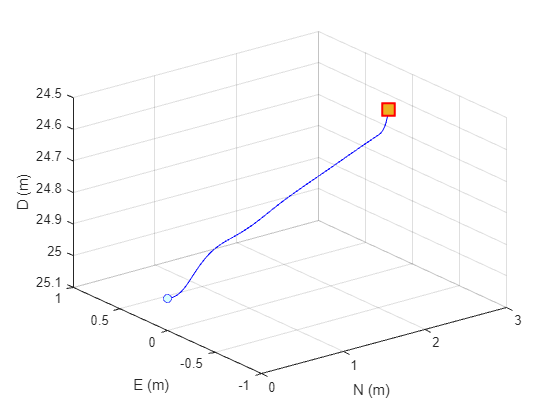

close("all")
figure(3)
plot3(out.logsout{1}.Values.N.Data,out.logsout{1}.Values.E.Data,out.logsout{1}.Values.D.Data,'-','Color','b');
hold on
plot3(ics.ita.N,ics.ita.E,ics.ita.D,'o','Color','b','MarkerSize',6,'MarkerFaceColor','#D9FFFF')
plot3(out.logsout{1}.Values.N.Data(end),out.logsout{1}.Values.E.Data(end),out.logsout{1}.Values.D.Data(end),'square','Color','r','MarkerSize',12,'MarkerEdgeColor','auto','LineWidth',2,'MarkerFaceColor',"#EDB120");
hold off
grid on
set(gca,'ZDir','reverse')
xlabel('N (m)')
ylabel('E (m)')
zlabel('D (m)')

%% load and read data of tether position in timetable 
    load("data\tether\pos_tether.mat");
    pos_tether.time = pos.time;
    pos_tether.data = pos.data; 

%% PLOTS

% figure(1)
% % subplot(3,1,1)
% yyaxis left
% plot(Sim.out.logsout{1}.Values.D,'b',"linewidth",1.5);
% ylabel("D (m)","FontWeight","bold","FontSize",12)
% ylim([-3 3])
% 
% 
% yyaxis right
% plot(Sim.out.logsout{10}.Values.Z,'r',"linewidth",1)
% ylabel("Z (N)","FontWeight","bold","FontSize",12)
% ylim([-1 150])
% 
% xlabel("t (s)","FontWeight","bold","FontSize",12)
% xlim([0 35])
% grid on
% title("Heave motion")

% subplot(3,1,2)
% plot(Sim.out.logsout{1}.Values.E,'b',"linewidth",1);
% ylabel("E (m)","FontWeight","bold","FontSize",12)
% title("Effect of yaw on sway motion","FontSize",12,"FontWeight","bold")
% grid on
% subplot(3,1,3)
% plot(Sim.out.logsout{1}.Values.D,'b',"linewidth",1);
% ylabel("D (m)","FontWeight","bold","FontSize",12)
% title("Effect of yaw on heave motion","FontSize",12,"FontWeight","bold")
% grid on


% plot(Sim.out.logsout{11}.Values.theta,'b',"linewidth",1)
% xlabel("t (s)","FontSize",12,"FontWeight","bold")
% ylabel("N (Nm)","FontSize",12,"FontWeight","bold")
% title("Moment during yaw motion along z_b axis","FontSize",12,"FontWeight","bold")
% xlim([15 30])
% grid on



% plot(Sim.out.logsout{1}.Values.N,"linewidth",1.5);
% hold on
% plot(Sim.out.logsout{1}.Values.E,"linewidth",1.5);
% plot(Sim.out.logsout{1}.Values.D,"linewidth",1.5);
% plot(Sim.out.logsout{1}.Values.phi,"linewidth",1.5);
% plot(Sim.out.logsout{1}.Values.theta,"linewidth",1.5);
% hold off
% xlabel('t (s)','FontWeight','bold')
% ylabel('N(m),E(m),D(m),phi(rad),theta(rad)');
% title("Effect of yaw motion on rest of the DOF")
% grid on
% legend("N","E","D","phi","theta")